# Datos de viento Vecindario

## Separar las distintas variables de viento

% Tratar los datos por años. Se obtiene una tabla con todos los datos de
% cada día y otra tabla con las medias diarias
[wind_table_all2020, meanWindTable2020] = extractWindVars(vecindario2020);
[wind_table_all2021, meanWindTable2021] = extractWindVars(vecindario2021);
[wind_table_all2022, meanWindTable2022] = extractWindVars(vecindario2022);
[wind_table_all2023, meanWindTable2023] = extractWindVars(vecindario2023);

daily_wind_table = vertcat(meanWindTable2020, meanWindTable2021, meanWindTable2022, meanWindTable2023);

## Representar componentes de viento

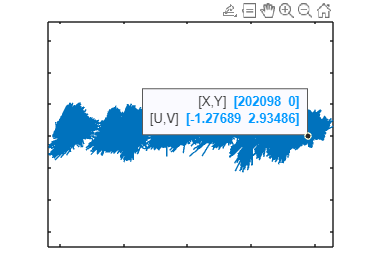

plotWindDirection(wind_table_all2020);

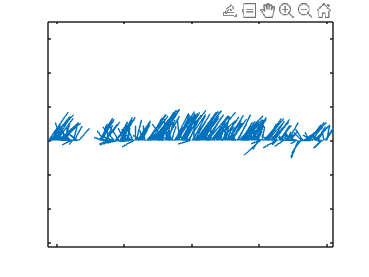

plotWindDirection(meanWindTable2020);

## Encontrar fechas repetidas

% En la dirección del viento
% [C, ia,ic] = unique(wind_dir_avg.date, 'first');
% indexToDupes = find(not(ismember(1:numel(wind_dir_avg.date),ia)))
% rept = wind_dir_avg.date(indexToDupes)
% 
% % En la velocidad del viento 
% [Cs, ias,ics] = unique(wind_speed_avg.date, 'first');
% indexToDupes = find(not(ismember(1:numel(wind_speed_avg.date),ias)))
% repts = wind_speed_avg.date(indexToDupes)

function [] = plotWindDirection(windTable)
    
    [xWind, yWind] = pol2cart((pi/180).*windTable.AvgWindDir, windTable.AvgWindSpeed);
    windTable = timetable2table(windTable);
    windTable.JulianDate = exceltime(windTable.date);
    
    sfact = 100; % or whatever looks nice
    x = 2019+(windTable.JulianDate-43466)./365.25; 
    y=x*0;
    quiver(x*sfact, y, xWind, yWind, 0, ".")
    axis equal;
    set(gca,'XTickLabel',[],'YTickLabel',[])


end